$$\mathbf x,\, \mathbf P$$ are the state mean and covariance. They correspond to $$x$$ and $$\sigma^2$$.

$$\mathbf F$$ is the state transition function. When multiplied by $\bf x$ it computes the prior.

bar = prior

not bar = posterior

## Prediction step

mean:                   $\bar{\mathbf{x}}=\mathbf{F}\mathbf{x}+\mathbf{B}\mathbf{u}$

covariance:         $\bar{\mathbf{P}}=\mathbf{F}\mathbf{P}\mathbf{F}+\mathbf{Q}$

## Update step

residual:               $\mathbf{e}=\mathbf{z}-\mathbf{H}\bar{\mathbf{x}}$

gain:                       $\mathbf{K}=\bar{\mathbf{P}}\mathbf{H}^T(\mathbf{H}\bar{\mathbf{P}}\mathbf{H}^T+\mathbf{R})^{-1}$

mean:                   $\mathbf{x}=\bar{\mathbf{x}}+\mathbf{K}\mathbf{e}$

covariance:         $\mathbf{P}=(\mathbf{I}-\mathbf{K}\mathbf{H})\bar{\mathbf{P}}$

clear variables; close all; clc

% number of states (estimates), solitamente n
dim_x = 2;
% number of measures (sensors), solitamente m
dim_z = 1;
% number of control input, solitamente p
dim_u = 1;
% discrete time step
dt = 0.1;
% initial condition: state mean and covariance
x0 = [10 0]';
P0 = diag([500 500]);
% state matrix
F = [1 dt; 0 1];
% measurement matrix
H = [1 0];
% control input matrix
B = zeros(dim_x,dim_u);
% process noise covariance matrix
% Q = [0.588 1.175; 1.175 2.35];
Q = diag([1e-5 1e-5]);
% measurement noise covariance matrix
R = 5;
% control input
u = 0;
% number of iterations
iterations = 500;
% generate measures
[truths,measures] = compute_dog_data(R, Q, iterations, dt);
% preallocate memory
x_posterior = cell(1, iterations);
P_posterior = cell(1, iterations);
x_prior = cell(1, iterations);
P_prior = cell(1, iterations);
residuals = cell(1, iterations);
gains = cell(1, iterations);
% apply starting conditions
x = x0;
P = P0;
% filtering
for ii = 1:iterations
    % predict
    [x,P] = mkf_predict(F,B,x,u,P,Q);
    x_prior{ii}=x;
    P_prior{ii}=P;
   
    % update
    z = measures{ii};
    e = mkf_innovation(H,z,x);
    K = mkf_gain(H,P,R);
    [x,P] = mkf_update(H,K,x,e,P,R);   
    x_posterior{ii}=x;
    P_posterior{ii}=P;
    gains{ii}=K;
    residuals{ii}=e;
end

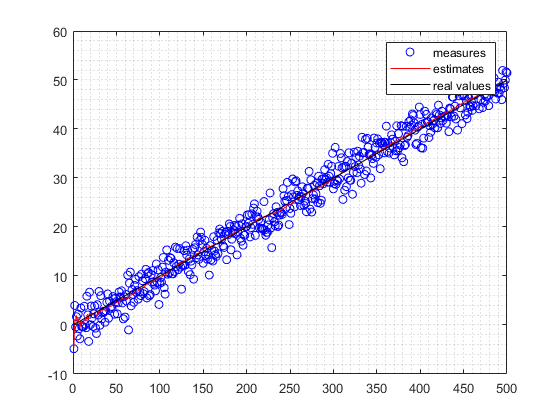

mx = cell2mat(x_posterior);
mz = cell2mat(measures);
mt = cell2mat(truths);
for ii=1:dim_z
    figure
    plot(mz(ii,:),'bo')
    hold on; grid minor;
   plot(mx(ii,:),'r')
    plot(mt(ii,:),'k')
end
legend('measures','estimates','real values')

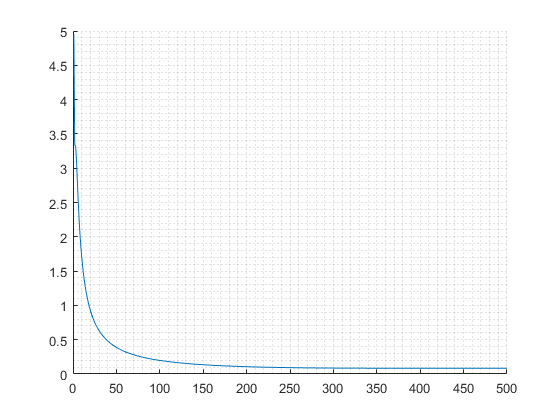

mP = cell2mat(P_posterior);
figure
hold on; grid minor;
plot(mP(1,1:2:end))

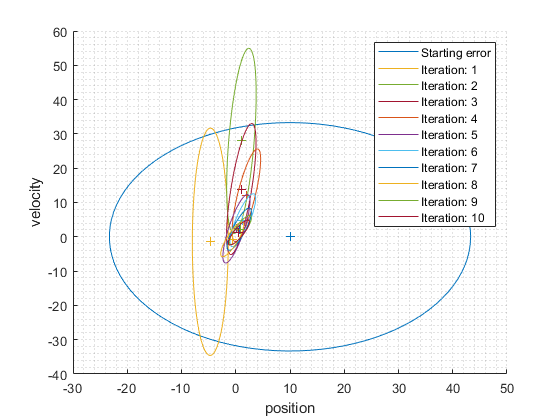


figure
hold on; grid minor;
legend
h = plotCovarianceEllipse(x0,P0,0.67);
h.set('DisplayName','Starting error');
xlabel('position')
ylabel('velocity')
for ii=1:1:10
    h = plotCovarianceEllipse(mx(:,ii),mP(:,2*ii-1:2*ii),0.67);
    h.set('DisplayName',['Iteration: ' num2str(ii)]);
end

me = cell2mat(residuals);
mean(me)

ans = -0.1016

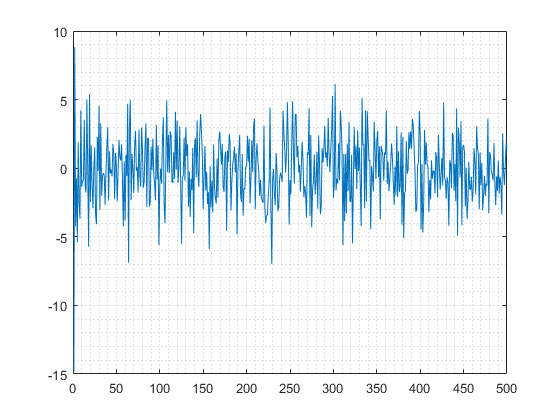

figure
plot(me)
grid minor

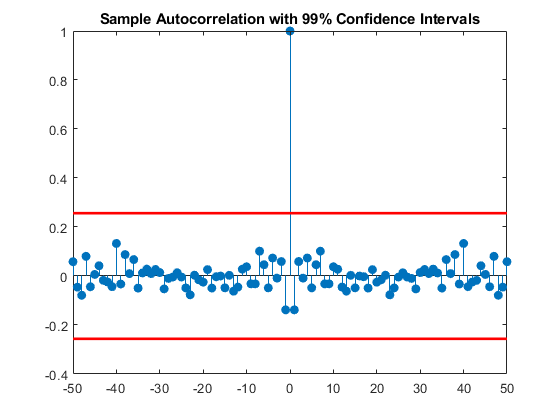

[xc,lags] = xcorr(me,50,'coeff');
conf99 = sqrt(2)*erfcinv(2*.01/2);
lconf = -conf99/sqrt(length(xc));
upconf = conf99/sqrt(length(xc));
figure
stem(lags,xc,'filled')
hold on
plot(lags,lconf*ones(size(lags)),'r','linewidth',2)
plot(lags,upconf*ones(size(lags)),'r','linewidth',2)
title('Sample Autocorrelation with 99% Confidence Intervals')

D = 0;
G = eye(2);
V = [0, 0];
sys = ss(F,[B, G],H,[D, V],dt);
[KEST,L,P] = kalman(sys,Q,R)


KEST =
 
  A = 
              x1_e       x2_e
   x1_e     0.9831        0.1
   x2_e  -0.001402          1
 
  B = 
               u1        y1
   x1_e         0   0.01688
   x2_e         0  0.001402
 
  C = 
              x1_e       x2_e
   y1_e     0.9833          0
   x1_e     0.9833          0
   x2_e  -0.001402          1
 
  D = 
               u1        y1
   y1_e         0   0.01674
   x1_e         0   0.01674
   x2_e         0  0.001402
 
Input groups:              
       Name        Channels
    KnownInput        1    
    Measurement       2    
                           
Output groups:                
         Name         Channels
    OutputEstimate       1    
    StateEstimate       2,3   
                              
Sample time: 0.1 seconds
Discrete-time state-space model.



L =     0.0169
    0.0014


P =     0.0851    0.0071
    0.0071    0.0012
